# Projet microgrid

## Lecture des fichiers

fichier_demande = 'demande.csv';
fichier_productible = "Ppv_kWc_inst_castres_Pdata_2020.csv";
Demande=readtable(fichier_demande);
Demande=table2array(Demande);
ProductibleSV=readtable(fichier_productible);
ProductibleSV=table2array(ProductibleSV);
Demande=Demande(:,4)/1000;   % trois colonnes de 0, il faut prendre la 4eme, Wh en kWh

% Paramètres dérivés des fichiers
N=length(Demande); % nombre d'heures dans une annee
donnees=[Demande ProductibleSV]; %variable fonction pour pas etre lus a chaque appel
time=linspace(1,N,N);  % utilise pour representation graphique

## Initialisation TEST

% Spv=10;
% Pel=5;
% Ppac=5;
% Qbatmax=20;

[b,c,d,e,f,g,h]=dimensionnetest([10,5,5,20],donnees);
cout_tot=b;
Qhydro=c;
deltahydro=d;
deltabat=e;
exces=f;
Qex=g;
Prod=h;
achats=zeros(1,N);
ventes=zeros(1,N);

for i=linspace(2,N,N-1)
    if Qex(i)-Qex(i-1) >=0
        achats(i)=Qex(i)-Qex(i-1);
    else
        ventes(i)=-(Qex(i)-Qex(i-1));
    end
end

## Plot

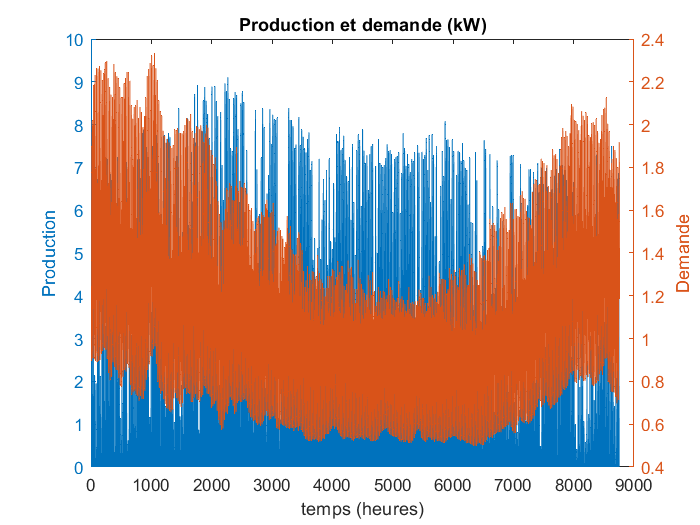

figure()
yyaxis left
plot(time,Prod,'-')
title('Production et demande (kW)')
ylabel('Production')
xlabel('temps (heures)')
yyaxis right
plot(time,Demande,'-')
ylabel('Demande')

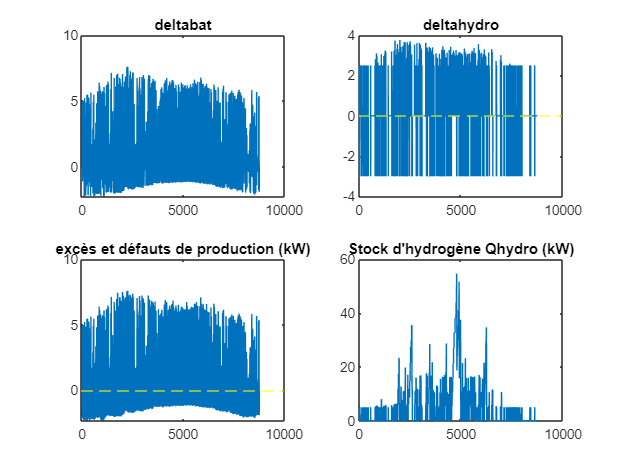

figure()
subplot(2,2,1)
plot(time,deltabat)
title('deltabat')

subplot(2,2,2)
plot(time,deltahydro)
title('deltahydro')
yline(0,'--y')

subplot(2,2,3)
plot(time,exces)
title('excès et défauts de production (kW)')
yline(0,'--y')

subplot(2,2,4)
plot(time,Qhydro)
title("Stock d'hydrogène Qhydro (kW)")

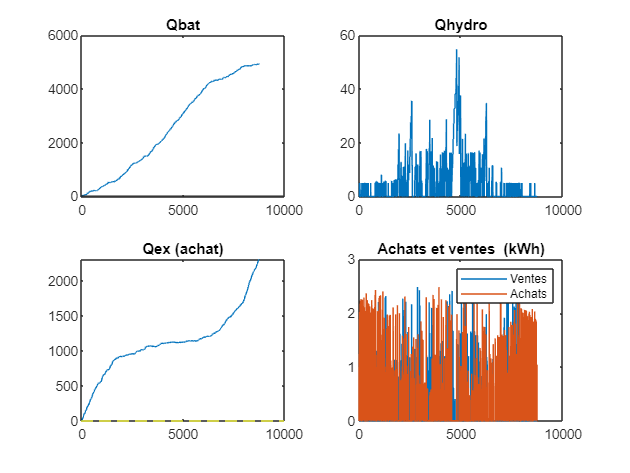

figure()
subplot(2,2,1)
plot(time,cumsum(deltabat))
title('Qbat')
yline(20) %Qbatmax test

subplot(2,2,2)
plot(time,Qhydro)
title('Qhydro')

subplot(2,2,3)
plot(time,Qex)
title('Qex (achat)')
yline(0,'--y')

subplot(2,2,4)
plot(time,ventes,time,achats)
title('Achats et ventes  (kWh)')
legend({'Ventes','Achats'})

## Optimisation (still nul ;( )

% Essaim de particules
[SolEss,Fvaless,exitflag] = particleswarm(@(x) dimensionne(x,donnees),4,zeros(1,4),1000*ones(1,4));

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


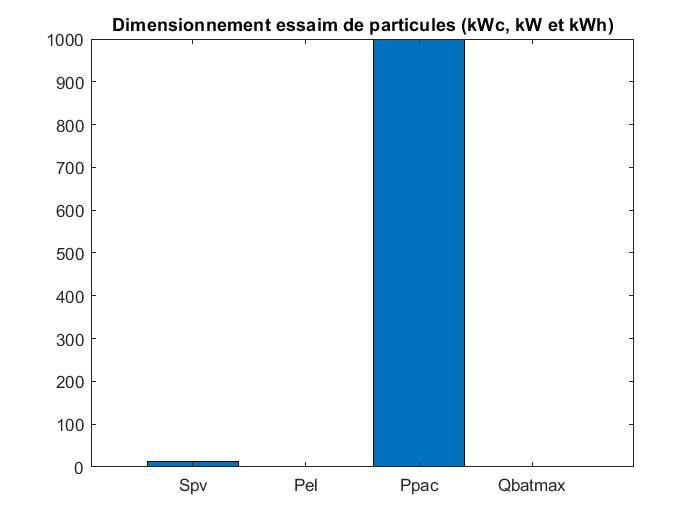

figure()
X = categorical({'Spv','Pel','Ppac','Qbatmax'});
X = reordercats(X,{'Spv','Pel','Ppac','Qbatmax'});
bar(X,SolEss);
title('Dimensionnement essaim de particules (kWc, kW et kWh)')

%%Global search 

problem = createOptimProblem('fmincon','x0',[10,5,5,20],'objective',@(x) dimensionne(x,donnees),...
     'lb',zeros(1,4),'ub',1000*ones(1,4));
gs= GlobalSearch();
[solGS, fvalGS] = run(gs,problem);

GlobalSearch stopped because it analyzed all the trial points.

76 out of 82 local solver runs converged with a positive local solver exit flag.


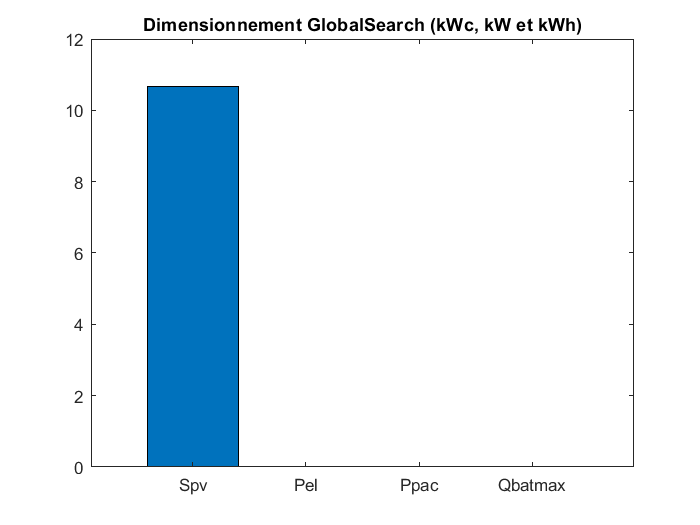

figure()
X = categorical({'Spv','Pel','Ppac','Qbatmax'});
X = reordercats(X,{'Spv','Pel','Ppac','Qbatmax'});
bar(X,solGS);
title('Dimensionnement GlobalSearch (kWc, kW et kWh)')


% Recuit simulé
[solrecuit,fval,flag,output]=simulannealbnd(@(x) dimensionne(x,donnees),[10,5,5,20],zeros(1,4),1000*ones(1,4));

Optimization terminated: change in best function value less than options.FunctionTolerance.


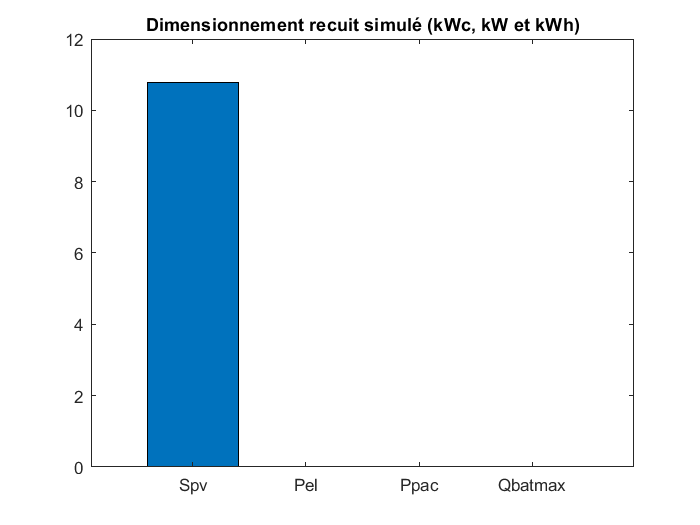

figure()
X = categorical({'Spv','Pel','Ppac','Qbatmax'});
X = reordercats(X,{'Spv','Pel','Ppac','Qbatmax'});
bar(X,solrecuit);
title('Dimensionnement recuit simulé (kWc, kW et kWh)')

figure()
X = categorical({'GS','Essaim','Recuit'});
X = reordercats(X,{'GS','Essaim','Recuit'});
bar(X,[solGS,SolEss,solrecuit]);

Error using bar
X must be same length as Y.

title('Dimensionnement recuit simulé (kWc, kW et kWh)')

## Function test

%code non détaillé, fonction écrite pour test, voir en bas la fonction
%détaillée

function [cout_tot,Qhydro,deltahydro,deltabat,exces,Qex,Prod]=dimensionnetest(x,donnees)
Spv=x(1);
Pel=x(2);
Ppac=x(3);
Qbatmax=x(4);
n = 20; % nombre d'annees
tauxprixrevente=1; 
ETAel=0.5;
ETApac=0.6;
Cout=[1200,2000,1000,400];
prix_achat=0.5;
Demande=donnees(:,1);
ProductibleSV=donnees(:,2);
N=length(Demande);
Init=zeros(1,N); 
Prod=ProductibleSV.*Spv; % Production solaire
Qbat=Init;
Qhydro=Init;
Qex=Init;
exces=Init;
deltabat=Init;
deltahydro=Init;
for a = linspace(1,N-1,N-1)
    %remise a zero des var locales
   
    if Demande(a) < Prod(a)    %%% Charger l'exces
        exces(a) = Prod(a) - Demande(a); 

        if Qbat(a) < Qbatmax    % Si bat non sat 

            if exces(a) <= Qbatmax-Qbat(a)  % Si bat non sat par exces
                deltabat(a)=exces(a);
                Qbat(a+1)=Qbat(a)+deltabat(a);
                Qhydro(a+1)=Qhydro(a);
                Qex(a+1)=Qex(a);

            else                % Si bat sat par exces
                Qbat(a+1)=Qbatmax;
                deltabat(a)=Qbatmax-Qbat(a);
                deltahydro(a)=ETAel*max(Pel,exces(a)-deltabat(a)); %charge donc Pel
                Qhydro(a+1)=Qhydro(a)+deltahydro(a);

                if deltahydro(a)==ETAel*Pel  % Si pile hydro saturee
                    Qex(a+1)=Qex(a)-tauxprixrevente*(exces(a)-deltabat(a) ...
                    -deltahydro(a));
                else 
                    Qex(a+1)=Qex(a);
                end
            end

        else           % Si bat sat
            deltahydro(a)=ETAel*max(Pel,exces(a));
            Qhydro(a+1)=Qhydro(a)+deltahydro(a);
            if deltahydro(a)==ETAel*Pel
               Qex(a+1)=Qex(a)-tauxprixrevente*(exces(a)-deltahydro(a));
            else
               Qex(a+1)=Qex(a); 
            end
        end

    elseif Demande(a) > Prod(a)     %% Combler manque
        exces(a)=-(Demande(a)-Prod(a));  % manque <0

        if Qbat(a) <= 0 % Batterie vide

            if Qhydro(a) <= 0 % Stock hydro et elec vide = achat
                Qex(a+1)=Qex(a)-exces(a);

            else % Stock hydro non vide
                deltahydro(a)=-ETApac*max(Ppac,-exces(a)); % decharge donc pac, et <0
                

                if Qhydro(a)+deltahydro(a) >= 0 %Qhydro ne part pas en negatif
                    Qhydro(a+1)=Qhydro(a)+deltahydro(a);
                    Qex(a+1) = Qex(a);

                else  % Hydro non suffisant pour combler
                    Qex(a+1) = Qex(a) + prix_achat*(-exces(a)+deltahydro(a));
                end
            end


        else    % Batterie non vide
            deltabat(a)=-min(Qbat(a),-exces(a));

            if deltabat(a)==Qbat(a)    % Batterie non suffisante
                deltahydro(a)=min(-ETApac*Ppac-exces(a)+deltabat(a));
                
                if deltahydro(a) == -ETApac*Ppac   % Bat et hydro non suffisants
                    Qhydro(a+1)=0;
                    Qex(a+1) = Qex(a) +(-exces + deltahydro(a) + deltabat(a));

                else   % hydro suffisant
                    Qhydro(a+1)=Qhydro(a)+deltahydro(a);
                    Qex(a+1) = Qex(a);
                end

            else                    % Bat suffisante
                Qbat(a+1) = Qbat(a) + deltabat(a);
                Qhydro(a+1) = Qhydro(a);
                Qex(a+1) = Qex(a);

            end
        end


    else                      %% Adequation parfaite prod demande
        Qhydro(a+1)=Qhydro(a);
        Qbat(a+1)=Qbat(a);
        Qex(a+1)=Qex(a);
    end
  
end
for a = linspace(1,N,N) 
    if Qbat(a)<0 || Qhydro(a)<0
      disp("Une batterie atteint une charge négative, impossible") ;
    end
end
cout_tot = x(1)*Cout(1)+x(2)*Cout(2) + x(3)*Cout(3) + ...
       x(4)*Cout(4)*max(1,ceil(n/20)) + n*Qex(N)*prix_achat ; 
end



%% Function




## Fonction à optimiser

%ici le code est détaillé
function [cout_tot]=dimensionne(x,donnees)
Spv=x(1);
Pel=x(2);
Ppac=x(3);
Qbatmax=x(4);

n = 20; % nombre d'annees
tauxprixrevente=1; % On considère qu'on revend l'électricité en surplus

% Donnees enonce
ETAel=0.5;
ETApac=0.6;
Cout=[1200,2000,1000,400];
prix_achat=0.5;

## Données

Demande=donnees(:,1);
ProductibleSV=donnees(:,2);
N=length(Demande);
Init=zeros(1,N);  % utilise pour initialiser les charges des batteries et autres variables

## Initialisation

Prod=ProductibleSV.*Spv; % Production solaire
Qbat=Init;
Qhydro=Init;
Qex=Init;
exces=Init;
deltabat=Init;
deltahydro=Init;

## Bloc logique

% Ce bloc permet de calculer le besoin en electricite importee 

for a = linspace(1,N-1,N-1)
    %remise a zero des var locales
   
    if Demande(a) < Prod(a)    %%% Charger l'exces
        exces(a) = Prod(a) - Demande(a); 

        if Qbat(a) < Qbatmax    % Si bat non sat 

            if exces(a) <= Qbatmax-Qbat(a)  % Si bat non sat par exces
                deltabat(a)=exces(a);
                Qbat(a+1)=Qbat(a)+deltabat(a);
                Qhydro(a+1)=Qhydro(a);
                Qex(a+1)=Qex(a);

            else                % Si bat sat par exces
                Qbat(a+1)=Qbatmax;
                deltabat(a)=Qbatmax-Qbat(a);
                deltahydro(a)=ETAel*max(Pel,exces(a)-deltabat(a)); %charge donc Pel
                Qhydro(a+1)=Qhydro(a)+deltahydro(a);

                if deltahydro(a)==ETAel*Pel  % Si pile hydro saturee
                    Qex(a+1)=Qex(a)-tauxprixrevente*(exces(a)-deltabat(a) ...
                    -deltahydro(a));
                else 
                    Qex(a+1)=Qex(a);
                end
            end

        else           % Si bat sat
            deltahydro(a)=ETAel*max(Pel,exces(a));
            Qhydro(a+1)=Qhydro(a)+deltahydro(a);
            if deltahydro(a)==ETAel*Pel
               Qex(a+1)=Qex(a)-tauxprixrevente*(exces(a)-deltahydro(a));
            else
               Qex(a+1)=Qex(a); 
            end
        end

    elseif Demande(a) > Prod(a)     %% Combler manque
        exces(a)=-(Demande(a)-Prod(a));  % manque <0

        if Qbat(a) <= 0 % Batterie vide

            if Qhydro(a) <= 0 % Stock hydro et elec vide = achat
                Qex(a+1)=Qex(a)-exces(a);

            else % Stock hydro non vide
                deltahydro(a)=-ETApac*max(Ppac,-exces(a)); % decharge donc pac, et <0
                

                if Qhydro(a)+deltahydro(a) >= 0 %Qhydro ne part pas en negatif
                    Qhydro(a+1)=Qhydro(a)+deltahydro(a);
                    Qex(a+1) = Qex(a);

                else  % Hydro non suffisant pour combler
                    Qex(a+1) = Qex(a) + prix_achat*(-exces(a)+deltahydro(a));
                end
            end


        else    % Batterie non vide
            deltabat(a)=-min(Qbat(a),-exces(a));

            if deltabat(a)==Qbat(a)    % Batterie non suffisante
                deltahydro(a)=min(-ETApac*Ppac-exces(a)+deltabat(a));
                
                if deltahydro(a) == -ETApac*Ppac   % Bat et hydro non suffisants
                    Qhydro(a+1)=0;
                    Qex(a+1) = Qex(a) +(-exces + deltahydro(a) + deltabat(a));

                else   % hydro suffisant
                    Qhydro(a+1)=Qhydro(a)+deltahydro(a);
                    Qex(a+1) = Qex(a);
                end

            else                    % Bat suffisante
                Qbat(a+1) = Qbat(a) + deltabat(a);
                Qhydro(a+1) = Qhydro(a);
                Qex(a+1) = Qex(a);

            end
        end


    else                      %% Adequation parfaite prod demande
        Qhydro(a+1)=Qhydro(a);
        Qbat(a+1)=Qbat(a);
        Qex(a+1)=Qex(a);
    end
  
end

% debugging charges des batteries

for a = linspace(1,N,N) 
    if Qbat(a)<0 || Qhydro(a)<0
      disp("Une batterie atteint une charge négative, impossible") ;
    end
end



## Calcul du coût

% nos données demande et production sont celles d'une année considérée type
% ainsi pour calculer sur plusieurs année on aura qu'à multiplier Qex considéré 
% importation annuelle constante par n
% Une batterie dure 20 ans d'ou le cout multiplié par n/20 (tronqué à
% l'entier inferieur, on prend 1 si n/20 < 1)

cout_tot = x(1)*Cout(1)+x(2)*Cout(2) + x(3)*Cout(3) + ...
       x(4)*Cout(4)*max(1,ceil(n/20)) + n*Qex(N)*prix_achat ; 

end



% disp('Solutions GlobalSearch');
% disp(['Puissance solaire: ', num2str(solGS(1)), ' kW']);
% disp(['Capacité de la batterie: ', num2str(solGS(1)), ' kWh']);
% disp(["Puissance de l'électrolyseur: ", num2str(solGS(1)), ' kWh']);
% disp(['Puissance de la pile à combustible: ', num2str(solGS(1)), ' kW']);

%% Conclusion

% Il reste des problèmes dans le bloc logique de la fonction objectif

%% Pistes d'amélioration

%Pour plus de réalisme:
%-limiter puissance décharge batterie 
%-limiter capacité de stockage hydrogène